# Tutorial: Horizon Edge Analysis

In this example, we will be using SONIC to analyze the edge on the Asteroid Bennu. We will first process the image by removing smear, which will make the edge clearer. Then, we will use SONIC to create scan lines along the direction of illumination on which we want to sample the intensity in the image. The sampled image along these lines will show an s-curve of intensity increase over the edge which occurs over some pixels. Finally, we can estimate the location of the actual edge in the image using SONIC's edge detection tools.

Begin by adding in the necessary SPICE directories, and loading in the kernels.

addpath('..\..\mice\lib\')
addpath('..\..\mice\src\mice')
cspice_furnsh('+examples/metakernel.tm')

### Process the Image: Remove Smear

Read in the image we are going to be analyzing, and store it in a SONIC image object. This will allow us to manipulate and use the image using SONIC's tools.

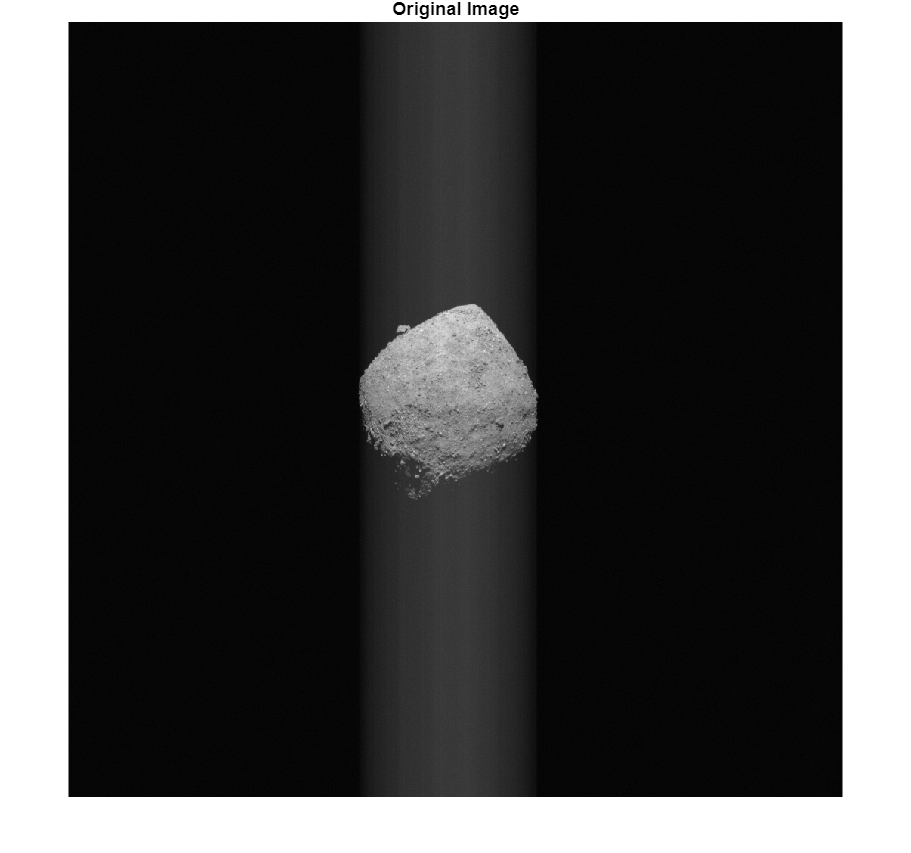

image_fn = "+examples/20181201T100711S900_map_L0pan.fits"; 
im_raw = flipud(fitsread(image_fn));

figure(1)
imshow(im_raw,[])
title('Original Image')

Before we can analyze the edge, we need to remove the smear present in the image.

t_exp = 0.45/1000; % ms to s conversion
t_readrow = 1*10^-6; % micros to s conversion
[im_cleaned] = removeSmearCCD(im_raw, t_exp, t_readrow);

Unrecognized function or variable 'removeSmearCCD'.

img_obj = sonic.Image(im_cleaned);

figure(2)
imshow(im_cleaned,[])
title('Smear Removed')

Now we read in the image meta data to get the direction of illumination in the image plane.

obs_t = 'Dec 12, 2018 10:07:11.900';
et = cspice_str2et(obs_t);
% get direction of illumination from sun to Bennu
r_S2B = cspice_spkezr('BENNU',et,'J2000','NONE','SUN');
r_S2B = sonic.Points3(r_S2B(1:3));

% get camera attitude wrt J2000
R_I2MC = cspice_pxform('J2000', 'ORX_OCAMS_MAPCAM', et);
% Account for frame definitions (we want x to right an y down, they have x up and y to the right)
R_MC2C = [cos(pi/2) sin(pi/2) 0; -sin(pi/2) cos(pi/2) 0; 0 0 1];
R_I2C = R_MC2C*R_I2MC;
att_I2C = sonic.Attitude(R_I2C);

% rotate 
r_sun2Bennu_C = sonic.Project.rotate(r_S2B, att_I2C);

% Project and store in Points2 object
u_illum = r_sun2Bennu_C.r3(1:2);
u_illum = u_illum./norm(u_illum);
u_illum_obj = sonic.Points2(u_illum);

Using the SONIC ScanLines method getParallelLines, we can generate evenly spaced (by drho), parallel scan lines in the image based on the direction of illumination. These scan lines contain both a Lines2 object and a vector of directionality in the image, where a positive (true) directionality indicates the scan is in the direction of increasing u, or in the case of verticle lines, scan from top to bottom. 

drho = 50;
scan_lines = sonic.ScanLines.getParallelLines(img_obj, drho, u_illum_obj);

Once we have the scan lines, we can call the Image method getLine to sample the image intensity along these scan lines. The getLine method uses bilinear interpolation to estimate the digital number at each location, so the intensity values lie exactly on the scan line, at intervals of one pixel along the lines. To visualize, we can plot these lines in the image to see that they align with the direction of illumination. Additionally, we can select one of the lines passing through Bennu, and analyze the pixel intensities over the change from background noise to Bennu.

[scan_values, scan_locs, line_lengths] = img_obj.getLine(scan_lines);

figure(3)
imshow(img_obj.DNmat,[])
hold on
for i = 1:length(scan_locs)
    plot_pts = scan_locs{i};
    if ~isempty(plot_pts)
        plot(plot_pts.r2(1,:), plot_pts.r2(2,:),'b')
    end
end
edge_analysis = scan_values{11};
figure(4)
plot(1:line_lengths(11),scan_values{11})
ylabel('Pixel Intensity')
xlabel('Distance along Scan Line (Pixel)')
title('Intensity value of Image over Scan')